%  sat4_main.m
 clear; clc; close all; 

%% ---------- 0) параметры реакционных колес ----------
reaction_wheel_params4;     % создаёт: B, Bplus, tau_max, Jr, IrR_local, …

disp('B = ');

B = 


disp(B);

    0.5774    0.5774   -0.5774   -0.5774
    0.5774   -0.5774    0.5774   -0.5774
    0.5774   -0.5774   -0.5774    0.5774



fprintf('— нули в строках roll/pitch? если да – махи вообще не дают момент по этим осям.\n');

— нули в строках roll/pitch? если да – махи вообще не дают момент по этим осям.




%%% ---------- 1) параметры КА (корпус + 4 колеса) ----------
ms = 2.6;                    % масса КА, кг
lx = 0.10; ly = 0.10; lz = 0.20;   % габариты, м

Is = (ms/12) * diag([ly^2+lz^2, lx^2+lz^2, lx^2+ly^2]);  % корпус
I  = Is + 4*IrR_local;        % + 4 одинаковых колеса, грубо
invI = inv(I);
disp('Is ='); disp(Is);

Is =
    0.0108         0         0
         0    0.0108         0
         0         0    0.0043



disp('I ='); disp(I);

I =
    0.0113         0         0
         0    0.0111         0
         0         0    0.0046



s = svd(B);
sigma_min = s(end);
M_test = [5e-3;5e-3;5e-3];

%% ---------- 2) начальное состояние ----------
omega0     = deg2rad([ 0;  0; 0]);   % рад/с
q0         = [1; 0; 0; 0];            % без поворота
omega_rw0  = zeros(4,1);              % скорости колес
x0 = [omega0; q0; omega_rw0];         % 3+4+4 = 11×1


%% ---------- 3) регулятор и целевая ориентация ----------
Ix = I(1,1);  Iy = I(2,2);  Iz = I(3,3);

% требования
Ts = 50;      % с
zeta = 0.8;

wn = 4 / (zeta * Ts);     % общая частота

% коэффициенты
Kp_x = Ix * wn^2;
Kd_x = 2 * zeta * wn * Ix;

Kp_y = Iy * wn^2;
Kd_y = 2 * zeta * wn * Iy;

Kp_z = Iz * wn^2;
Kd_z = 2 * zeta * wn * Iz;

% Kp = diag([Kp_x, Kp_y, Kp_z]);
% Kd = diag([Kd_x, Kd_y, Kd_z]);
 Kp = diag([0 0 0]);
 Kd = diag([0 0 0]);



% пусть нужно: yaw=10°, pitch=20°, roll=15° (ZYX-порядок)
 eul = deg2rad([0,0,0]);
 q_des = eul2quat(eul,'ZYX').';   % вернёт 1×4, транспонируем в 4×1

M_dist = [1e-5;0;0;];                   % возмущающий момент, Н·м
use_tikh = 1; 
pars.lambda = 10;
pars.fail_idx = 1;  % индекс маховика, выходящего из строя
pars.t_fail  = 20; % время отказа
pars.I       = I;
pars.invI    = invI;
pars.Kp      = Kp;
pars.Kd      = Kd;
pars.q_des   = q_des;
pars.B       = B;                     % 3×4
pars.Bplus   = Bplus;                 % 4×3
pars.tau_max = tau_max;
pars.Jr      = Jr;                    % скаляр
pars.M_dist  = M_dist;
pars.omega_lim = 6000;
if use_tikh
pars.alloc      = @(T) ridge_alloc(T, pars.B,      pars.lambda);
pars.alloc_free = @(T,Bf) ridge_alloc(T, Bf,        pars.lambda);
else
    pars.alloc = @(T) pinv(pars.B) * T;
    pars.alloc_free = @(T,Bf) pinv(Bf)*T;
end

%% ---------- 6) интегрирование ODE ----------
tspan = [0 500];
opts  = odeset('MaxStep', 0.1);

global log_tau log_t idx log_omega_s
idx = []; log_tau = []; log_t = []; log_omega_s = [];
[t, x] = ode45(@(t,x) rhs_attitude4(t, x, pars), tspan, x0, opts);

## 6) plots


omega_body = x(:,1:3);  
omega_teor = M_dist(1,1)/I(1,1) * t

omega_teor =          0
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0001
    0.0002
    0.0002
    0.0002


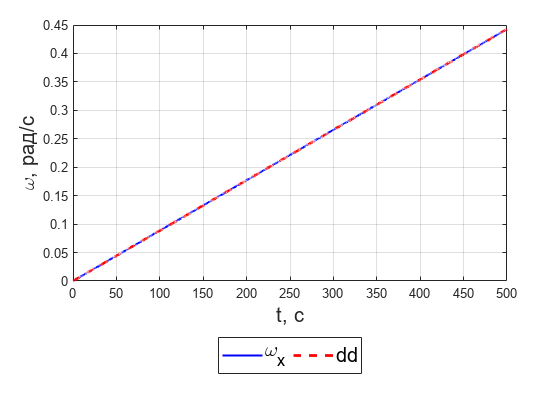


figure;
h =plot(t, omega_body(:,1),'LineWidth',2);
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % r1

hold on
plot(t,omega_teor, '--','Color','r','LineWidth',2)
xlabel('t, с','FontSize',15); ylabel('\omega, рад/c', 'FontSize',15);
grid on;
hold on
legend({'\omega_x','теоретическая \omega_x'}, ...
       'Location','southoutside', ...
       'Orientation','horizontal','FontSize',15);

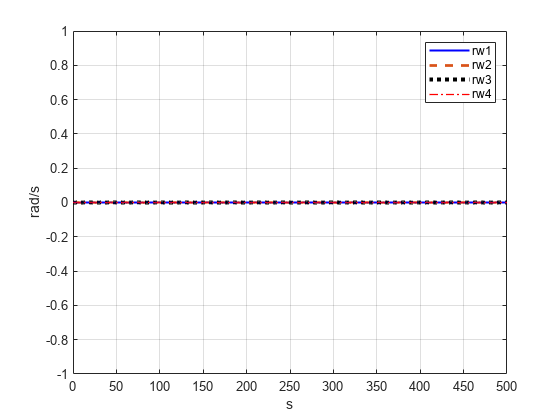




omega_rw = x(:,8:11);

figure;
h = plot(t,omega_rw);
legend('rw1','rw2','rw3','rw4'); xlabel('s'); ylabel('rad/s'); grid on;
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % r1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % r2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % r3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % r4

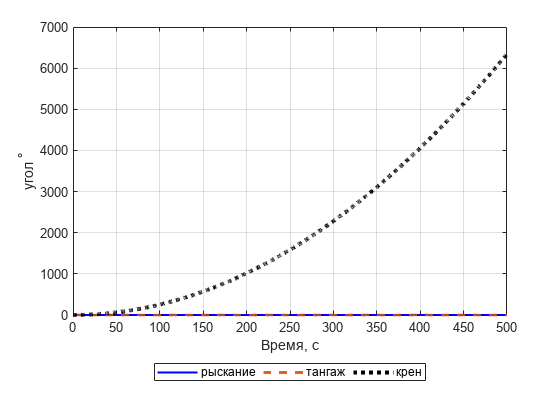

q = x(:,4:7);
q = q./vecnorm(q,2,2);
euler = zeros(length(t),3);
% --- кватернионы -> углы Эйлера (градусы) ---
euler_deg = zeros(length(t),3);
for k = 1:length(t)
    R = quat2rotm(q(k,:));
    euler_deg(k,:) = rad2deg( rotm2eul(R,'ZYX') );
end
% --- делаем непрерывными и возвращаем в градусы ---
euler_cont = rad2deg( unwrap( deg2rad(euler_deg), [], 1) );  % 3 столбца

figure;
h = plot(t, euler_cont.');      % 3×N  (правильное имя!)
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % yaw
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % pitch
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % roll
legend({'рыскание','тангаж','крен'}, ...
       'Location','southoutside', ...
       'Orientation','horizontal');
 xlabel('Время, с'); ylabel('угол ^\circ');
grid on

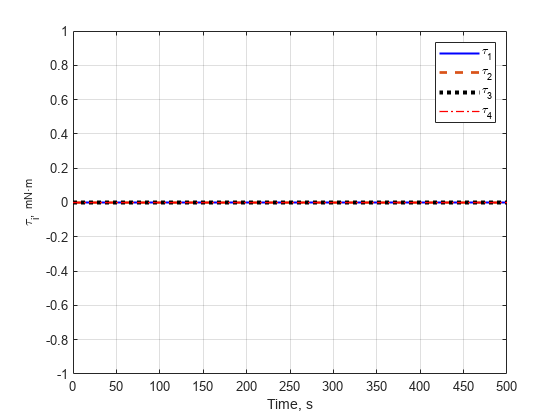



k = idx-1;                        % фактическое число записей
figure; 
h = plot(log_t(1:k), 1e3*log_tau(:,1:k).');
xlabel('Time, s');  ylabel('\tau_i,  mN·m');
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % tau1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % tau2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % tau3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % tau4

legend('\tau_1','\tau_2','\tau_3','\tau_4');  grid on;